ЛАБОРАТОРНА РОБОТА №4

з навчальної дисципліни «Математичне моделювання систем і процесів»

Виконав:

Студент 5 курсу

Групи ФФ-21мн

Бондар О.В.

Перевірив:

Гордійко Н.О.

Варіант №1 

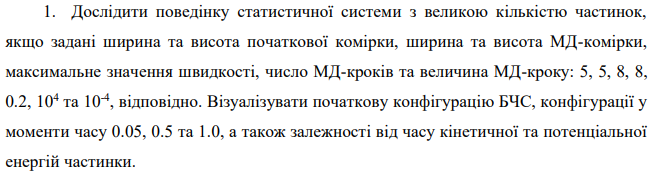

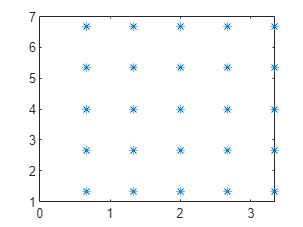

clearvars;
Nx=5;
Ny=5;
Lx=8;
Ly=8;

Vmax=0.2;
dt=10^(-4);
Ni=10^4;


N=Nx*Ny;

Posrow=Ly/(Ny+1); Poscol=Lx/(Nx+1);
i=1;
for Rows=1:Ny
    for Col=1:Nx
        x(i)=Poscol*Col/2; 
        y(i)=Posrow*Rows; 
        Vx(i)=Vmax*(2*rand(1)-1); 
        Vy(i)=Vmax*(2*rand(1)-1);
        i=i+1;
    end
end
plot(x,y, '*')


T=0;
T1=0.05;
T2=0.5;
T3=1.0;


RV=init(Lx,Ly,Nx,Ny,Vmax,T) 

RV =     0.6667    1.3333   -0.1128    0.1032
    1.3333    1.3333    0.0388   -0.1037
    2.0000    1.3333   -0.1756    0.0306
    2.6667    1.3333    0.1607   -0.0326
    3.3333    1.3333    0.0109   -0.0792
    0.6667    2.6667    0.0773   -0.0667
    1.3333    2.6667   -0.0208    0.1109
    2.0000    2.6667    0.1332    0.2150
    2.6667    2.6667   -0.0043   -0.1133
    3.3333    2.6667   -0.1635   -0.0657


accfunc=Acc(RV,Lx,Ly,N)

accfunc = 1.0e+03 *

   -6.1681    0.0023         0
    0.0017    0.0031         0
   -0.0000    0.0032         0
   -0.0017    0.0031         0
    6.1681    0.0023         0
   -6.1676    0.0000         0
    0.0019    0.0001         0
   -0.0000    0.0001         0
   -0.0019    0.0001         0
    6.1676    0.0000         0


z1=Fx(x,y)

z1 =    -0.3706   -0.1322   -0.0294   -0.0071   -0.0020   -0.0034   -0.0035   -0.0022   -0.0011   -0.0005   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


z2=Fy(x,y)

z2 =    -0.7413   -0.1322   -0.0196   -0.0035   -0.0008   -0.0135   -0.0071   -0.0029   -0.0011   -0.0004   -0.0009   -0.0007   -0.0004   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000



% verletfunc=Verlet(RV,Lx,Ly,N,dt)

md=MD(Lx,Ly,N,Ni,dt,RV)



RV1=init(Lx,Ly,Nx,Ny,Vmax,T1) 
accfunc1=Acc(RV1,Lx,Ly,N)
md1=MD(Lx,Ly,N,Ni,dt,RV1)

RV2=init(Lx,Ly,Nx,Ny,Vmax,T1) 
accfunc2=Acc(RV2,Lx,Ly,N)
md2=MD(Lx,Ly,N,Ni,dt,RV2)

RV3=init(Lx,Ly,Nx,Ny,Vmax,T1) 
accfunc3=Acc(RV3,Lx,Ly,N)
md3=MD(Lx,Ly,N,Ni,dt,RV3)




% розрахунок енергій
Ep=0;
for i=1:N-1
    for j=i+1:N
        Dx=x(i)-x(j);
        if abs(Dx)>Lx/2
            Dx=Dx-sign(Dx)*Lx;
        end
        Dy=y(i)-y(j);
        if abs(Dy)>Ly/2
            Dy=Dy-sign(Dy)*Ly;
        end
        r=(Dx^2+Dy^2).^0.5; Ep=Ep+4*(1/r.^12-1/r.^6);
    end
end
Ek=0;
for i=1:N
    Ek=Ek+0.5*(Vx(i)^2+Vy(i)^2);
end
Ep
Ek
Esum = Ep+Ek 


